# Actividad 1.6

Para la actividad se pide hacer 3 trayectorias: para esto lo que se hace es sacar v = m/tf y w = theta/tf, con el fin de poder mover el robot hacia adelante y rotarlo respectivamente. 

Estor esto que al necesitar hacer una a la ves los cambios principales se ven en la velocidades de cada uno de las trayectorias.

u = 0 1 0 1 0 1;

w = 1 0 1 0 1 0;

el formato anterior es el usado para ir intercalando los cambios de de velocidades.

#### Trayectoria Gato.

Para la trayectoria del gato se usa un tiempo final de 35 y un ts 0.5

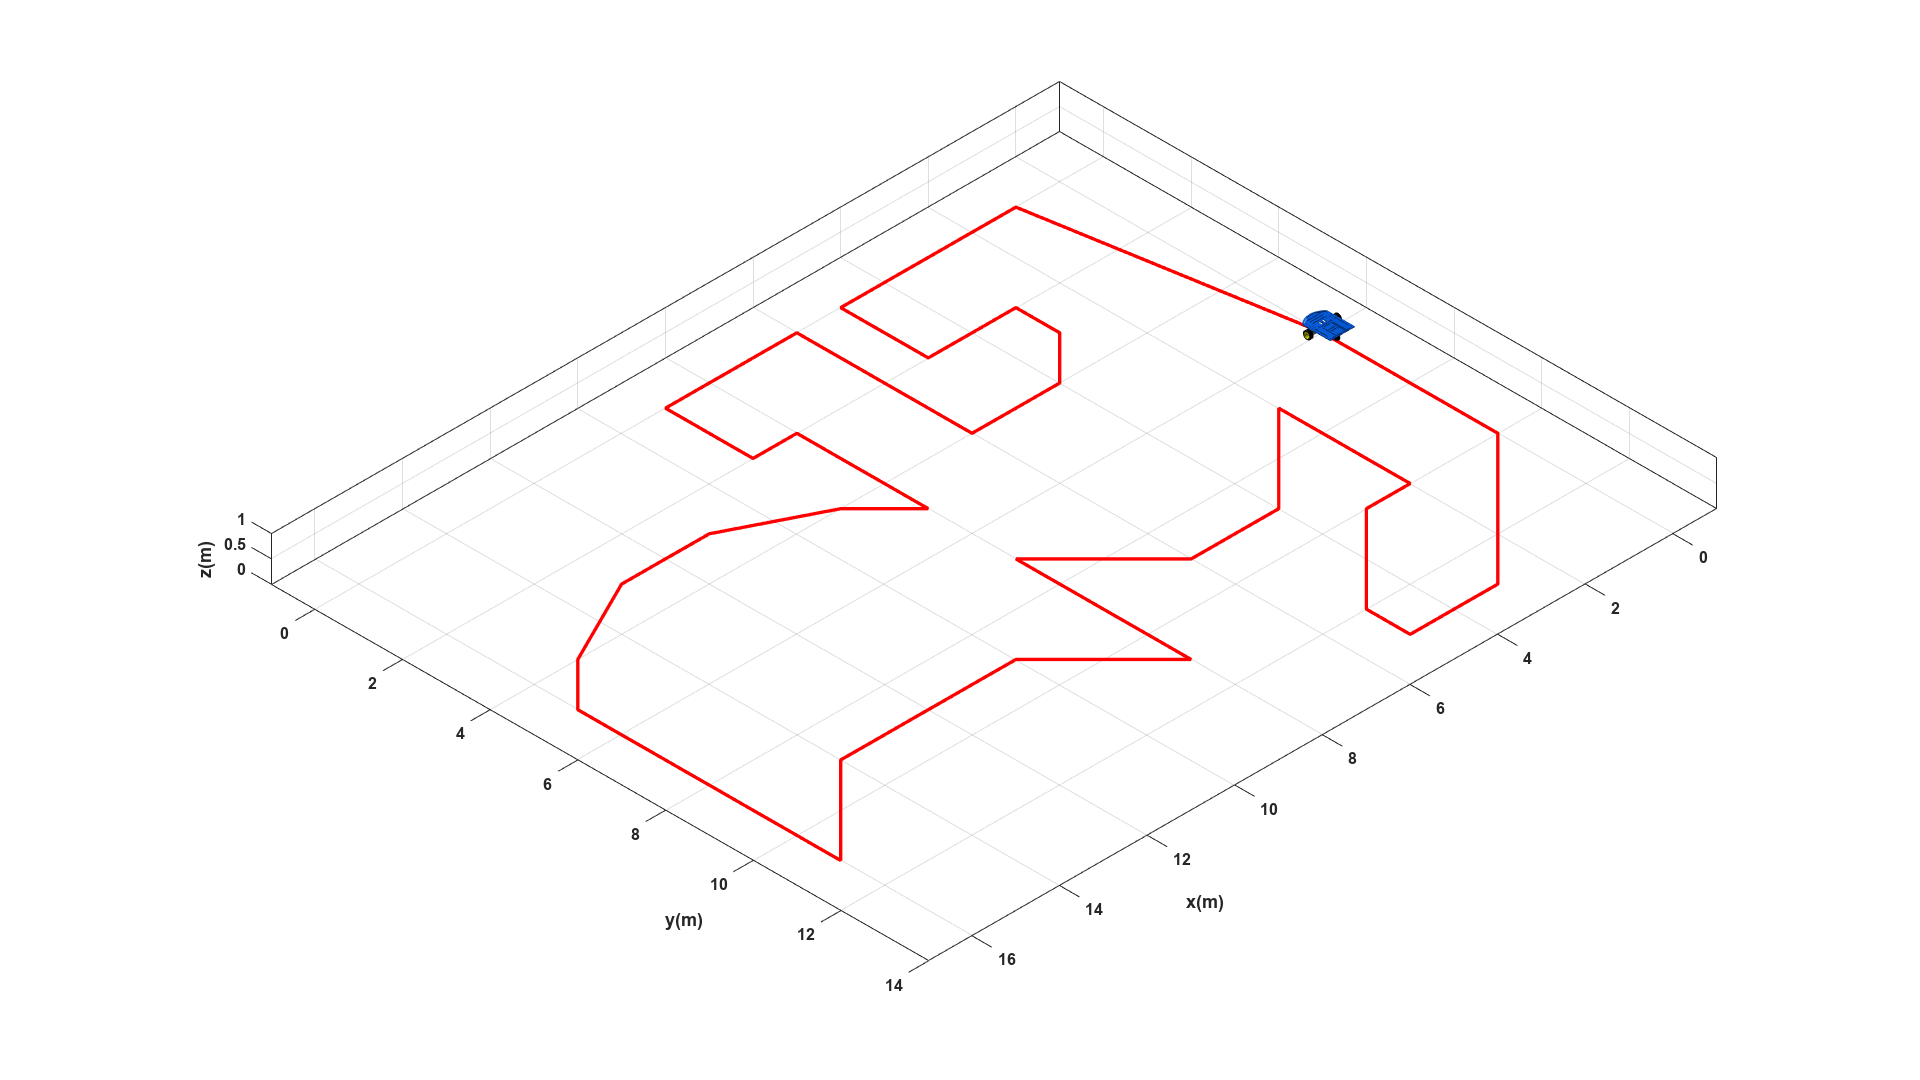

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 35;           % Tiempo de simulacion en segundos (s)
ts = 0.5;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 6;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u =[0, (sqrt((1-0)^2+(0-6)^2))/ts, 0, sqrt((5-1)^2 +(0-0)^2)/ts, 0, (sqrt((5-5)^2+(2-0)^2))/ts, 0, (sqrt((3-5)^2+(2-2)^2))/ts,0,(sqrt((3-3)^2+(3-2)^2))/ts,0,(sqrt((4-3)^2+(4-3)^2))/ts,0,(sqrt((6-4)^2+(4-4)^2))/ts,0,(sqrt((6-6)^2+(0-4)^2))/ts,0,(sqrt((9-6)^2+(0-0)^2))/ts,0,(sqrt((9-9)^2+(0-2)^2))/ts,0,(sqrt((8-9)^2+(2-2)^2))/ts,0,(sqrt((8-8)^2+(5-2)^2))/ts,0,(sqrt((9-8)^2+(4-5)^2))/ts,0,(sqrt((11-9)^2+(3-4)^2))/ts,0,(sqrt((13-11)^2+(3-3)^2))/ts,0,(sqrt((15-13)^2+(4-3)^2))/ts,0,(sqrt((16-15)^2+(5-4)^2))/ts,0,(sqrt((16-16)^2+(11-5)^2))/ts,0,(sqrt((14-16)^2+(9-11)^2))/ts,0,(sqrt((10-14)^2+(9-9)^2))/ts,0,(sqrt((8-10)^2+(11-9)^2))/ts,0,(sqrt((8-8)^2+(7-11)^2))/ts,0,(sqrt((6-8)^2+(9-7)^2))/ts,0,(sqrt((4-6)^2+(9-9)^2))/ts,0,(sqrt((2-4)^2+(7-9)^2))/ts,0,(sqrt((2-2)^2+(10-7)^2))/ts,0,(sqrt((3-2)^2+(10-10)^2))/ts,0,(sqrt((5-3)^2+(12-10)^2))/ts,0,(sqrt((5-5)^2+(13-12)^2))/ts,0,(sqrt((3-5)^2+(13-13)^2))/ts,0,(sqrt((0-3)^2+(10-13)^2))/ts,0,(sqrt((0-0)^2+(6-10)^2))/ts,0,0,0,0,0,0,0,0,0,0];
w =[(atan2(0-6, 1-0))/ts, 0, -((atan2(0-6, 1-0))/ts)+((atan2(0-0, 5-1))/ts), 0, -((atan2(0-0, 5-1))/ts)+(atan2(2-0, 5-5))/ts, 0, -((atan2(2-0, 5-5))/ts)+(atan2(2-2, 2-5))/ts, 0,-((atan2(2-2, 2-5))/ts)+(atan2(3-2, 3-3))/ts,0,-((atan2(3-2, 3-3))/ts)+(atan2(4-3, 4-3))/ts,0,-((atan2(4-3, 4-3))/ts)+(atan2(4-4, 6-4))/ts,0,-((atan2(4-4, 6-4))/ts)+(atan2(0-4, 6-6))/ts,0,-((atan2(0-4, 6-6))/ts)+(atan2(0-0, 9-6))/ts,0,-((atan2(0-0, 9-6))/ts)+(atan2(2-0, 9-9))/ts,0,-((atan2(2-0, 9-9))/ts)+(atan2(2-2, 8-9))/ts,0,-((atan2(2-2, 8-9))/ts)+(atan2(5-2, 8-8))/ts,0,-((atan2(5-2, 8-8))/ts)+(atan2(4-5, 9-8))/ts,0,-((atan2(4-5, 9-8))/ts)+(atan2(3-4, 11-9))/ts,0,-((atan2(3-4, 11-9))/ts)+(atan2(3-3, 13-11))/ts,0,-((atan2(3-3, 13-11))/ts)+(atan2(4-3, 15-13))/ts,0,-((atan2(4-3, 15-13))/ts)+(atan2(5-4, 16-15))/ts,0,-((atan2(5-4, 16-15))/ts)+(atan2(11-5, 16-16))/ts,0,-((atan2(11-5, 16-16))/ts)+(atan2(9-11, 14-16))/ts,0,-((atan2(9-11, 14-16))/ts)+(atan2(9-9, 10-14))/ts,0,-((atan2(9-9, 10-14))/ts)+(atan2(11-9, 8-10))/ts,0,-((atan2(11-9, 8-10))/ts)+(atan2(7-11, 8-8))/ts,0,-((atan2(7-11, 8-8))/ts)+(atan2(9-7, 6-8))/ts,0,-((atan2(9-7, 6-8))/ts)+(atan2(9-9, 4-6))/ts,0,-((atan2(9-9, 4-6))/ts)+(atan2(7-9, 2-4))/ts,0,-((atan2(7-9, 2-4))/ts)+(atan2(10-7, 2-2))/ts,0,-((atan2(10-7, 2-2))/ts)+(atan2(10-10, 3-2))/ts,0,-((atan2(10-10, 3-2))/ts)+(atan2(12-10, 5-3))/ts,0,-((atan2(12-10, 5-3))/ts)+(atan2(13-12, 5-5))/ts,0,-((atan2(13-12, 5-5))/ts)+(atan2(13-13, 3-5))/ts,0,-((atan2(13-13, 3-5))/ts)+(atan2(10-13, 0-3))/ts,0,-((atan2(10-13, 0-3))/ts)+(atan2(6-10, 0-0))/ts,0,0,0,0,0,0,0,0,0,0];

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
   
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([135 35]); % Orientacion de la figura
axis([-1 17 -1 14 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

#### Tratectoria mariposa.

Para la trayectoria del gato se usa un tiempo final de 30 y un ts 0.5

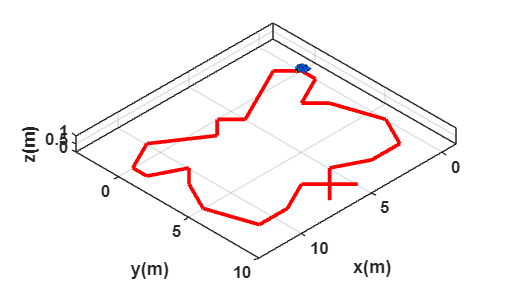

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 30;           % Tiempo de simulacion en segundos (s)
ts = 0.5;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 0;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u =[0, (sqrt((1-0)^2+(-1-0)^2))/ts, 0, sqrt((5-1)^2 +(1+1)^2)/ts, 0, (sqrt((1-0)^2+(-1-0)^2))/ts, 0, (sqrt((1-0)^2+(-1-0)^2))/ts,0,(sqrt((10-7)^2+(-1-1)^2))/ts,0,(sqrt((12-10)^2+(0+1)^2))/ts,0,(sqrt((12-12)^2+(1-0)^2))/ts,0,(sqrt((10-12)^2+(2-1)^2))/ts,0,(sqrt((11-10)^2+(3-2)^2))/ts,0,(sqrt((12-11)^2+(5-3)^2))/ts,0,(sqrt((11-12)^2+(8-5)^2))/ts,0,(sqrt((9-11)^2+(8-8)^2))/ts,0,(sqrt((7-9)^2+(7-8)^2))/ts,0,(sqrt((5-7)^2+(9-7)^2))/ts,0,(sqrt((6-5)^2+(8-9)^2))/ts,0,(sqrt((7-6)^2+(9-8)^2))/ts,0,(sqrt((5-7)^2+(7-9)^2))/ts,0,(sqrt((3-5)^2+(8-7)^2))/ts,0,(sqrt((1-3)^2+(8-8)^2))/ts,0,(sqrt((0-1)^2+(6-8)^2))/ts,0,(sqrt((1-0)^2+(3-6)^2))/ts,0,(sqrt((2-1)^2+(2-3)^2))/ts,0,(sqrt((0-2)^2+(1-2)^2))/ts,0,(sqrt((0-0)^2+(0-1)^2))/ts,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0];
w =[(atan2(-1-0, 1-0))/ts, 0, -((atan2(-1-0, 1-0))/ts)+((atan2(0+1, 3-1))/ts), 0, -((atan2(0+1, 3-1))/ts)+(atan2(-1-0, 1-0))/ts, 0, -((atan2(-1-0, 1-0))/ts)+(atan2(1-0, 7-6))/ts, 0, -((atan2(1-0, 7-6))/ts)+(atan2(-1-1, 10-7))/ts,0,-((atan2(-1-1, 10-7))/ts)+(atan2(0+1, 12-10))/ts,0,-((atan2(0+1, 12-10))/ts)+(atan2(1-0, 12-12))/ts,0,-((atan2(1-0, 12-12))/ts)+(atan2(2-1, 10-12))/ts,0,-((atan2(2-1, 10-12))/ts)+(atan2(3-2, 11-10))/ts,0,-((atan2(3-2, 11-10))/ts)+(atan2(5-3, 12-11))/ts,0,-((atan2(5-3, 12-11))/ts)+(atan2(8-5, 11-12))/ts,0,-((atan2(8-5, 11-12))/ts)+(atan2(8-8, 9-11))/ts,0,-((atan2(8-8, 9-11))/ts)+(atan2(7-8, 7-9))/ts,0,-((atan2(7-8, 7-9))/ts)+(atan2(9-7, 5-7))/ts,0,-((atan2(9-7, 5-7))/ts)+(atan2(8-9, 6-5))/ts,0,-((atan2(8-9, 6-5))/ts)+(atan2(9-8, 7-6))/ts,0,-((atan2(9-8, 7-6))/ts)+(atan2(7-9, 5-7))/ts,0,-((atan2(7-9, 5-7))/ts)+(atan2(8-7, 3-5))/ts,0,-((atan2(8-7, 3-5))/ts)+(atan2(8-8, 1-3))/ts,0,-((atan2(8-8, 1-3))/ts)+(atan2(6-8, 0-1))/ts,0,-((atan2(6-8, 0-1))/ts)+(atan2(3-6, 1-0))/ts,0,-((atan2(3-6, 1-0))/ts)+(atan2(2-3, 2-1))/ts,0,-((atan2(2-3, 2-1))/ts)+(atan2(1-2, 0-2))/ts,0,-((atan2(1-2, 0-2))/ts)+(atan2(0-1, 0-0))/ts,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0];

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([135 35]); % Orientacion de la figura
axis([-1 13 -3 10 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

#### Trayectoria murcielago.

Para la trayectoria del gato se usa un tiempo final de 36 y un ts 0.5

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 36;             % Tiempo de simulacion en segundos (s)
ts = 0.5;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = -3;    % Posicion inicial eje x
y1(1) = 2;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%


u = [ 0, 8.485, 0, 6, 0, 8.485, 0, 14.422, 0, 14.422, 0, 17.088, 0, 8, 0, 4.472, 0, 18, ...
    0, 4.472, 0, 5, 0, 17.888, 0, 5.45, 0, 5.8, 0, 10, 0, 1.8, 0, 4.6, 0, 5, 0, 3, 0, 9.5, ...
    0, 9.5, 0, 3, 0, 5, 0, 4.6, 0, 1.8, 0, 10, 0, 5.8, 0, 5.45, 0, 17.888, 0, 5, 0, ... 
    18, 0, 4.472, 0, 6.472, 0, 8, 0, 17.088, 0, 14.422, 0]; % Velocidad lineal de referencia (m/s)
    

w = [-pi/2, 0, 2.79253, 0, 2.79253, 0, -5.759, 0, 3.4, 0, 1.047, 0, 1.007, 0, -5.085, 0, ...
    1.287, 0, 1.48353, 0, -5.03412, 0, 0.2, 0, -1.3472, 0, 0.65, 0, 0.2, 0, 0.3, 0, 0.1, 0, ...
    0.0708, 0, 0.07, 0, 0.85, 0, -4.28, 0, 0.85, 0, 0.07, 0, 0.0708, 0, 0.1, 0, 0.3, 0, 0.2, 0, ...
    0.65, 0, -1.3472, 0, 0.2, -5.03412, 0, 1.48353, 0, 1.287, 0, -5.085, 0, 1.007, 0, 1.047, ...
    0, 2.4, 0]; % Velocidad angular de referencia (rad/s)


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([135 35]); % Orientacion de la figura
axis([-30 30 -30 20 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');


